# 

# **Multiple Linear Regression (General Approach)**

- **The functions **`polyfit`** and **`polyval`** in MATLAB are built ****specifically**** for one-dimensional polynomial fitting**

- **Use the general approach for multiple linear regression instead**

Fit a line to the following data:

`x1 = [1 1 1 2 2 2 3 3 3]';`

`x2 = [1 2 3 1 2 3 1 2 3]';`

`y = [10.5 13.9 15.1 11.5 14.7 18.9 14.2 18.5 20.1]';`

Determine the $r^2$ and $s_{\frac{y}{x}}$.  

Use the least-squares fit to predict the value of y when $x_1$ = 1.5 and $x_2$ = 1.5.

Rounding a decimal number to four decimal places.

$r^2$ = ?

$s_{\frac{y}{x}}$ = ?

$x_1$ = 1.5,  $x_2$ = 1.5,  y = ?

## **Data**

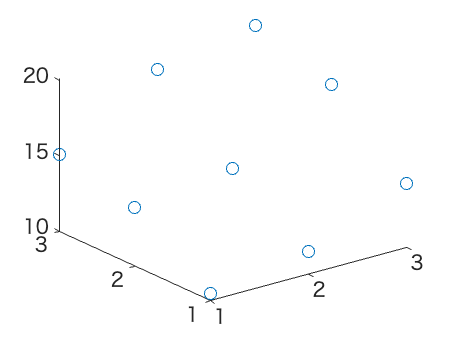

x1 = [1 1 1 2 2 2 3 3 3]';
x2 = [1 2 3 1 2 3 1 2 3]';
y = [10.5 13.9 15.1 11.5 14.7 18.9 14.2 18.5 20.1]';
plot3(x1, x2, y, 'o')

## Z-Matrix (Design Matrix)


$$Z=\underset{\left(1\;{\mathrm{is}\;z}_0 \right)}{\left\lbrack \begin{array}{ccc}
1 & x_{1,1}  & x_{2,1} \\
1 & x_{1,2}  & x_{2,2} \\
\vdots  & \vdots  & \vdots \\
1 & x_{1,n}  & x_{2,n} 
\end{array}\right\rbrack } =\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & 2\\
1 & 1 & 3\\
1 & 2 & 1\\
1 & 2 & 2\\
1 & 2 & 3\\
1 & 3 & 1\\
1 & 3 & 2\\
1 & 3 & 3
\end{array}\right\rbrack$$


Z = [ones(size(y)), x1, x2]

Z =      1     1     1
     1     1     2
     1     1     3
     1     2     1
     1     2     2
     1     2     3
     1     3     1
     1     3     2
     1     3     3


## **Solve for unknown parameters (**$a$**)**


$$\begin{array}{l}
\left\lbrack {\left\lbrack \mathit{\mathbf{Z}}\right\rbrack }^{\mathit{\mathbf{T}}} \left\lbrack \mathit{\mathbf{Z}}\right\rbrack \right\rbrack \left\lbrace a\right\rbrace =\left\lbrace {\left\lbrack \mathit{\mathbf{Z}}\right\rbrack }^{\mathit{\mathbf{T}}} \left\lbrace \mathit{\mathbf{y}}\right\rbrace \right\rbrace \\
\left\lbrace a\right\rbrace ={\left\lbrack {\left\lbrack \mathit{\mathbf{Z}}\right\rbrack }^{\mathit{\mathbf{T}}} \left\lbrack \mathit{\mathbf{Z}}\right\rbrack \right\rbrack }^{-1} \left\lbrace {\left\lbrack \mathit{\mathbf{Z}}\right\rbrack }^{\mathit{\mathbf{T}}} \left\lbrace \mathit{\mathbf{y}}\right\rbrace \right\rbrace 
\end{array}$$


*(see as ****Z****a = ****Y****, in MATLAB as *`a`` = Z \ Y`*)*

**NOTE: **`\`* (left division operator) *is used to solve a system of linear equations in the form of $A\cdot x=b$.

% unknowns (coefficient vector)
a = (Z' * Z) \ (Z' * y)

a =     4.8667
    2.2167
    2.9833


## **Plot data and best-fitted curve (Optional)**

Linear function of $x_1$ and $x_2$: $y=a_0 +a_1 x_1 +a_2 x_2 +e=\underset{\mathrm{design}\;\mathrm{matrix}}{Z} \cdot \underset{\mathrm{coefficient}\;\mathrm{vector}}{a} +e$

x1p = linspace(min(x1), max(x1), 100)

x1p =     1.0000    1.0202    1.0404    1.0606    1.0808    1.1010    1.1212    1.1414    1.1616    1.1818    1.2020    1.2222    1.2424    1.2626    1.2828    1.3030    1.3232    1.3434    1.3636    1.3838    1.4040    1.4242    1.4444    1.4646    1.4848    1.5051    1.5253    1.5455    1.5657    1.5859    1.6061    1.6263    1.6465    1.6667    1.6869    1.7071    1.7273    1.7475    1.7677    1.7879    1.8081    1.8283    1.8485    1.8687    1.8889    1.9091    1.9293    1.9495    1.9697    1.9899


x2p = linspace(min(x2), max(x2), 100)

x2p =     1.0000    1.0202    1.0404    1.0606    1.0808    1.1010    1.1212    1.1414    1.1616    1.1818    1.2020    1.2222    1.2424    1.2626    1.2828    1.3030    1.3232    1.3434    1.3636    1.3838    1.4040    1.4242    1.4444    1.4646    1.4848    1.5051    1.5253    1.5455    1.5657    1.5859    1.6061    1.6263    1.6465    1.6667    1.6869    1.7071    1.7273    1.7475    1.7677    1.7879    1.8081    1.8283    1.8485    1.8687    1.8889    1.9091    1.9293    1.9495    1.9697    1.9899


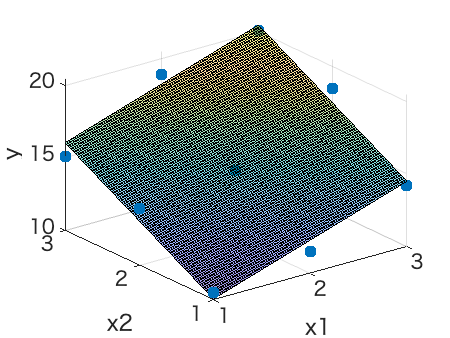

% `meshgrid` creates continuous grid
% returns 2-D grid coordinates based on the coordinates contained in vectors x and y
[X1, X2] = meshgrid(x1p, x2p);
% use X1 and X2 to plot the 3D graph, gives us 100x100 matrix
% but using .*x1p and .*x2p gives us 1x100 matrix, not good for graphing
yp = a(1) + a(2)*X1 + a(3)*X2;
scatter3(x1, x2, y, 'filled')  % plot raw data
hold on
surf(x1p, x2p, yp, 'FaceAlpha', 0.5)  % plot fitted plane
xlabel('x1')
ylabel('x2')
zlabel('y')

## Find $S_r$

**(the sum of the squares of the residuals between the data points and the best-fitted curve)**

sr = sum((y - (Z*a)).^2)

sr = 4.3967

## Find $S_t$

**(the sum of the squares of the residuals between the data points and the mean)**

st = sum((y - mean(y)).^2)

st = 87.2800

## Find $r_2$

**(coefficient of determination)**

r2 = 1 - (sr/st) % correct

r2 = 0.9496

## Find $S_{\frac{y}{x}}$

**(standard error of the estimate)**

n = length(y);
syx = sqrt(sr / (n - 3)) % correct

syx = 0.8560

## Find Prediction Value of $y$

($x_1 =x_2 =1\ldotp 5$)

y_pred = a(1) + a(2)*1.5 + a(3)*1.5 % correct

y_pred = 12.6667